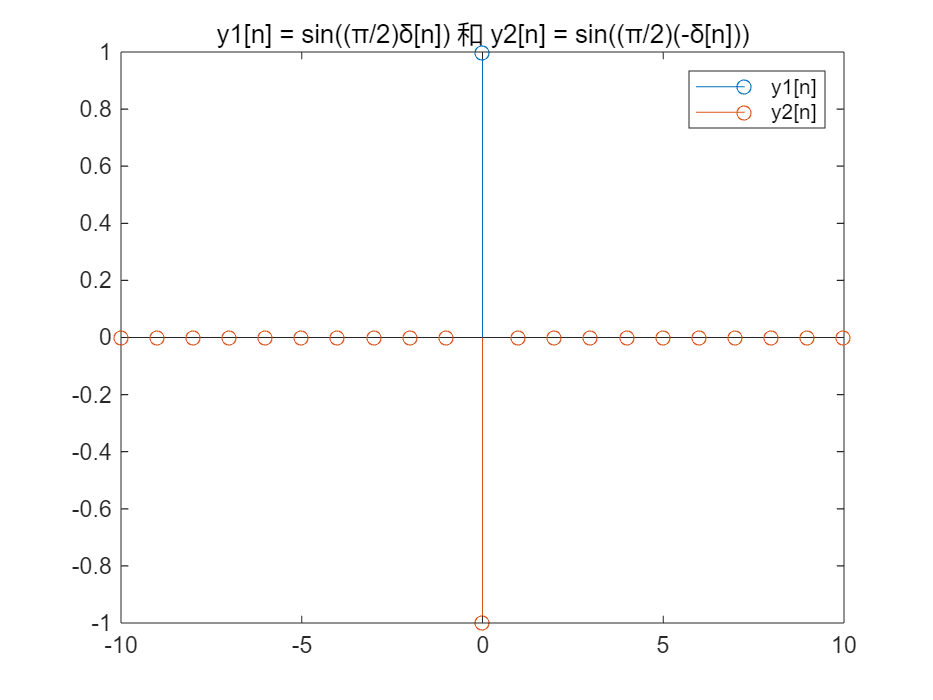

% 定义信号
n = -10:10;
x1 = [zeros(1,10), 1, zeros(1,10)]; % δ[n]
x2 = [zeros(1,10), -1, zeros(1,10)]; % -δ[n]

% 计算输出
y1 = sin(pi/2 * x1);
y2 = sin(pi/2 * x2);

% 绘制信号
figure;
stem(n, y1);
hold on;
stem(n, y2);
title('y1[n] = sin((π/2)δ[n]) 和 y2[n] = sin((π/2)(-δ[n]))');
legend('y1[n]', 'y2[n]');


% 判断是否可逆
if norm(y1 - y2) < 1e-10
    disp('系统是可逆的');
else
    disp('系统不是可逆的');
end

系统不是可逆的
